% 1st order
clc; clear; close all
tic
format long

%% parameter settings
tol = 1e-5;
kmax = 20000;
N = 129;
x = linspace(-1, 1, N);
z = linspace(-1, 1, N);
[X, Z] = meshgrid(x, z);

%% examples
% c_exact = 3 - 2.5 * exp(-X.^2 / 2);
% c_exact = ones(N);
c_exact = 1+0.2*sin(pi*(Z+1)/2).*sin(3*pi*(X+0.55));
% load c_data/example_4
% load D:\桌面\codes\examples&results\results\example_4\c

%% source point
fixed_pt_list = [];
for n = 1:4
    fixed_pt_list = [fixed_pt_list; 0, 20, n*25];
    fixed_pt_list = [fixed_pt_list; 0, N-19, n*25];
    fixed_pt_list = [fixed_pt_list; 0, n*25, 20];
    fixed_pt_list = [fixed_pt_list; 0, n*25, N-19];
end   


%% iteration
I = N;
J = N;
dx = (x(end)-x(1)) / (I-1); dy = (z(end) - z(1)) / (J-1);

niu = 1;
c0 = c_solver2(c_exact, zeros(I, J), dx, dy, niu);
c = c0;

energy = 1e9;
relative_error = 1e9;
alpha_f = 1e-4; alpha_0 = 0.1;
for k = 1: kmax
    
    energy_p = 0;
    cstar = 0;
    parfor p_num = 1:size(fixed_pt_list, 1)
        T = TravelTime_solver(c, fixed_pt_list(p_num, :), dx, dy, I, J);
        T_star = TravelTime_solver(c_exact, fixed_pt_list(p_num, :), dx, dy, I, J);
        energy_p = energy_p + EnergyFun(T, T_star, dx, dy);
        cstar = cstar + cStarSolver(T, T_star, dx, I, J, c);
    end
    
    if norm(cstar)*dx*dy < tol
        break
    end

    energy = [energy, energy_p];
    relative_error = [relative_error, norm(c-c_exact)/norm(c_exact)];
    if mod(k, 10) == 0
       disp(k)
       disp(norm(cstar)*dx*dy)
    end

        alpha = 0.3;
    % alpha = alpha_f + 0.5*(alpha_0 - alpha_f) * (1 + cos(pi*k / kmax));
    c = c + alpha * cstar;
   
end

    10


     1.520822087970160e-04


    20


     9.737730777341517e-05


    30


     6.794822628502371e-05


    40


     5.356390483967475e-05


    50


     4.478516510553611e-05


    60


     3.882629661732398e-05


    70


     3.378710476984678e-05


    80


     2.975410346820496e-05


    90


     2.613905851837266e-05


   100


     2.317681666349895e-05


   110


     2.069165797336744e-05


   120


     1.858277996887789e-05


   130


     1.680327427053420e-05


   140


     1.529493160728019e-05


   150


     1.401423916405764e-05


   160


     1.291844794711988e-05


   170


     1.196949100507361e-05


   180


     1.114513676913579e-05


   190


     1.042789670974513e-05


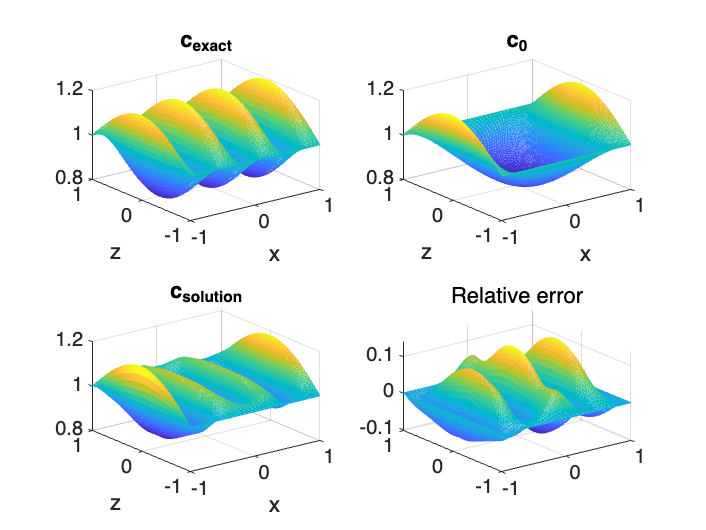


%% results and visualization
figure
subplot(2, 2, 1)
mesh(x, z, c_exact)
xlabel x
ylabel z
title('c_{exact}', 'FontWeight','bold')
subplot(2, 2, 2)
mesh(x, z, c0)
xlabel x
ylabel z
title('c_0', 'FontWeight','bold')
subplot(2, 2, 3)
mesh(x, z, c)
xlabel x
ylabel z
title('c_{solution}', 'FontWeight','bold')
subplot(2, 2, 4)
mesh(x, z, (c-c_exact)./c_exact)
title('Relative error')

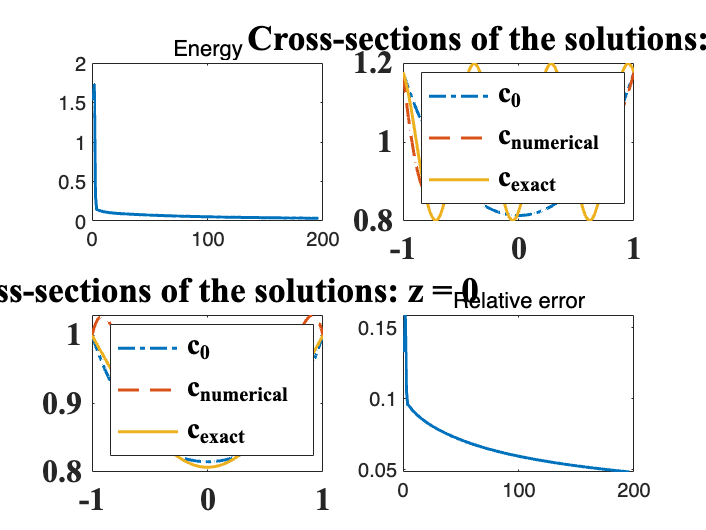


figure
subplot(2, 2, 1)
plot(energy(2:end), 'linewidth', 1.5)
title('Energy')

subplot(2, 2, 2)
plot(z, c0(60, :), '-.', 'linewidth', 1.5)
hold on
plot(z, c(60, :), '--', 'linewidth', 1.5)
hold on
plot(z, c_exact(60, :), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
title('Cross-sections of the solutions: x = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 4)
plot(relative_error(2:end), 'linewidth', 1.5)
title('Relative error')


toc

历时 35.608810 秒。
